## The analytic solution by assuming N0=CN

s_o=3;%set to the desired ohmicity
A=@(w) exp(w);
C=@(w) sqrt(A(-w))./(1+sqrt(A(-w)));
b=@(w) w.^(2+s_o).*C(w).*(1-C(w))./(C(w)+(1-C(w)).*A(-w)) .* ...
    (A(2*w)./abs(1-A(w)).^3 + A(-3*w)./abs(1-A(-w)).^3);
ww=0:1e-5:10;
wopt=ww(b(ww)==max(b(ww)))

wopt = 5.2706

copt=C(wopt)

copt = 0.0669

bopt=b(wopt)

bopt = 18.4880

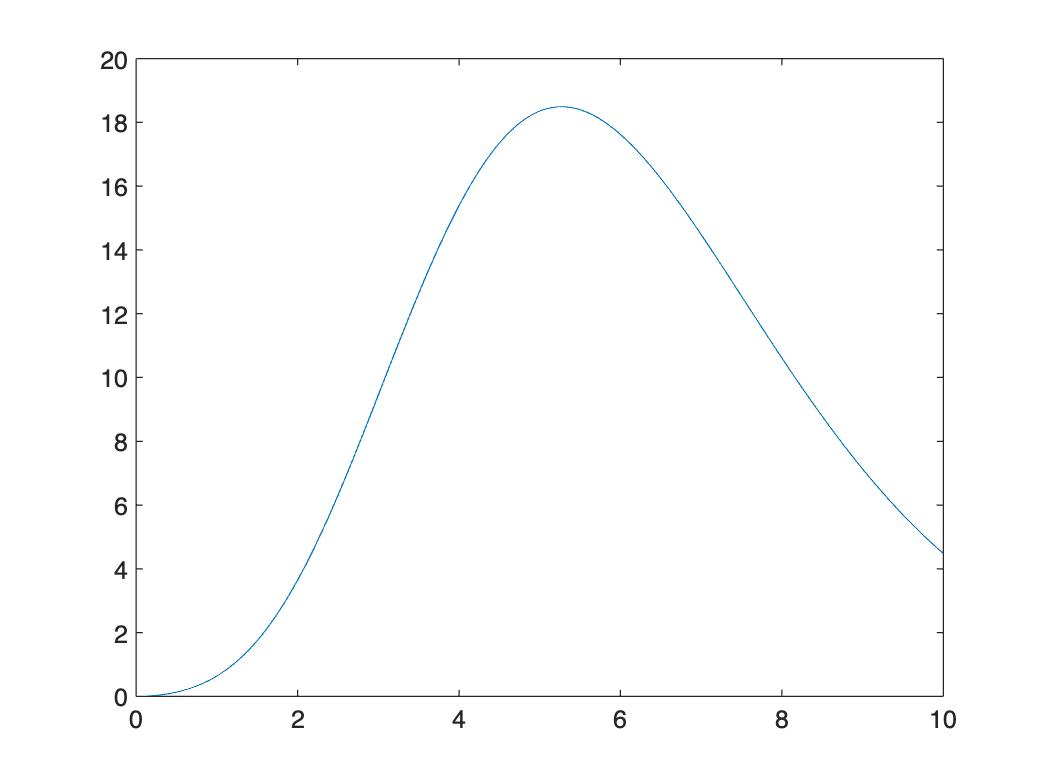

figure
plot(ww,b(ww))

## Analytics

% syms D d w n
% assume(n,'integer')
% assume(D,'integer')
% assume(d,'integer')
% assume(d<=D & d>=0)
% assume(w>0)
% p=1/(d+(D-d)*exp(-w));
%     F=d*(D-d)*w^2 * ( p*exp(2*w)/(exp(w)+1)^3 ...
%         + (1-d*p)/(D-d)*exp(-2*w)/(exp(-w)+1)^3);
% dwF=simplify(diff(F,w))
% syms FF(w)
% eqn=diff(FF)==dwF

$$dwF = \frac{d\,w\,{\mathrm{e}}^{w}\,\left(\text{D}-d\right)\,\left(2\,\text{D}-2\,d+\text{D}\,w-d\,w+2\,\text{D}\,{\mathrm{e}}^{w}+2\,\text{D}\,{\mathrm{e}}^{2\,w}+2\,\text{D}\,{\mathrm{e}}^{3\,w}+2\,d\,{\mathrm{e}}^{4\,w}+2\,d\,w\,{\mathrm{e}}^{w}+3\,\text{D}\,w\,{\mathrm{e}}^{2\,w}-6\,d\,w\,{\mathrm{e}}^{2\,w}+2\,d\,w\,{\mathrm{e}}^{3\,w}-d\,w\,{\mathrm{e}}^{4\,w}-2\,\text{D}\,w\,{\mathrm{e}}^{w}\right)}{{\left({\mathrm{e}}^{w}+1\right)}^{4}\,{\left(\text{D}-d+d\,{\mathrm{e}}^{w}\right)}^{2}}$$

% simplify(dsolve(eqn,'Implicit',true))

## The average FI (F^emp)

syms w T x N N0 gamma s

$$eqn(w) = \frac{\partial }{\partial w}\mathrm{FF}\left(w\right)=\frac{d\,w\,{\mathrm{e}}^{w}\,\left(\text{D}-d\right)\,\left(2\,\text{D}-2\,d+\text{D}\,w-d\,w+2\,\text{D}\,{\mathrm{e}}^{w}+2\,\text{D}\,{\mathrm{e}}^{2\,w}+2\,\text{D}\,{\mathrm{e}}^{3\,w}+2\,d\,{\mathrm{e}}^{4\,w}+2\,d\,w\,{\mathrm{e}}^{w}+3\,\text{D}\,w\,{\mathrm{e}}^{2\,w}-6\,d\,w\,{\mathrm{e}}^{2\,w}+2\,d\,w\,{\mathrm{e}}^{3\,w}-d\,w\,{\mathrm{e}}^{4\,w}-2\,\text{D}\,w\,{\mathrm{e}}^{w}\right)}{{\left({\mathrm{e}}^{w}+1\right)}^{4}\,{\left(\text{D}-d+d\,{\mathrm{e}}^{w}\right)}^{2}}$$

assume(w>0)

$$ans = \text{D}+d\,{\mathrm{e}}^{w}\neq d\wedge C_{1}\,d+d^{2}\,w^{2}\,{\mathrm{e}}^{3\,w}+\mathrm{FF}\left(w\right)\,{\left({\mathrm{e}}^{w}+1\right)}^{3}\,\left(\text{D}-d+d\,{\mathrm{e}}^{w}\right)+d^{2}\,w^{2}\,{\mathrm{e}}^{w}+2\,C_{1}\,d\,{\mathrm{e}}^{w}=C_{1}\,\text{D}+3\,C_{1}\,\text{D}\,{\mathrm{e}}^{2\,w}+C_{1}\,\text{D}\,{\mathrm{e}}^{3\,w}+2\,C_{1}\,d\,{\mathrm{e}}^{3\,w}+C_{1}\,d\,{\mathrm{e}}^{4\,w}+3\,C_{1}\,\text{D}\,{\mathrm{e}}^{w}+\text{D}\,d\,w^{2}\,{\mathrm{e}}^{3\,w}+\text{D}\,d\,w^{2}\,{\mathrm{e}}^{w}\wedge {\mathrm{e}}^{w}\neq -1$$

assume(T>0)
assume(s>1);
N=2^2;
for N00=1:N
N0=N00;
evec=[zeros(1,N0), w*ones(1,N-N0)];
sw=length(evec);
pvec=exp(-evec/T);
pvec=pvec/sum(pvec);
P=diag(pvec);
dP=diff(pvec,T);
nmat=sym(zeros(sw,sw));
wmat=0*nmat;
for iw=1:sw
    for jw=1:sw
        wij=evec(1,iw)-evec(1,jw);
        wmat(iw,jw)=wij;
        nmat(iw,jw)=1./(exp(wij/T)-1);
    end
end
Gamma=gamma*abs(wmat).*abs(transpose(nmat));
Gamma=Gamma-diag(sum(Gamma,1));
Gamma=nan2zero(Gamma);
simplify(Gamma);
simplify(P\Gamma);
%%%
F_emp=-1/2*dP/P*Gamma*transpose(dP);
simplify(F_emp);
%%%
F_emp=0;
for iw=1:sw
    for jw=1:sw
        dummy=dP(1,iw)*Gamma(iw,jw)/pvec(1,iw)*dP(1,jw);
        F_emp=F_emp+dummy;
    end
end
F_emp=-1/2*F_emp;
simplify(F_emp)
end

$$ans = \frac{9\,\gamma \,w^{3}\,{\mathrm{e}}^{w/T}\,\left({\mathrm{e}}^{\frac{2\,w}{T}}+1\right)}{2\,T^{4}\,\left({\mathrm{e}}^{w/T}-1\right)\,{\left({\mathrm{e}}^{w/T}+3\right)}^{3}}$$

$$ans = \frac{\gamma \,w^{3}\,{\mathrm{e}}^{w/T}\,\left({\mathrm{e}}^{\frac{2\,w}{T}}+1\right)}{T^{4}\,\left({\mathrm{e}}^{w/T}-1\right)\,{\left({\mathrm{e}}^{w/T}+1\right)}^{3}}$$

$$ans = \frac{9\,\gamma \,w^{3}\,{\mathrm{e}}^{w/T}\,\left({\mathrm{e}}^{\frac{2\,w}{T}}+1\right)}{2\,T^{4}\,\left({\mathrm{e}}^{w/T}-1\right)\,{\left(3\,{\mathrm{e}}^{w/T}+1\right)}^{3}}$$

$$ans = 0$$

syms w T N0 N s
assume(w>0)
assume(T>0)
assume(s>1);
nB=1/(exp(w/T)-1)

$$nB = \frac{1}{{\mathrm{e}}^{w/T}-1}$$

p0=1./(N0+(N-N0)*exp(-w/T))

$$p0 = \frac{1}{N_{0}+{\mathrm{e}}^{-\frac{w}{T}}\,\left(N-N_{0}\right)}$$

p1=exp(-w/T)./(N0+(N-N0)*exp(-w/T));
dp0=diff(p0,T)

$$dp0 = -\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}\,\left(N-N_{0}\right)}{T^{2}\,{\left(N_{0}+{\mathrm{e}}^{-\frac{w}{T}}\,\left(N-N_{0}\right)\right)}^{2}}$$

dp1=-N0/(N-N0)*dp0;
wi0j0=limit(w.^s.*nB,w,0);%both belonging to the GS manifold, but not equal
wi1j1=0;%both belonging to the ES manifold, but not equal
wi1j0=w.^s.*abs(nB);%first from the GS, the other from the ES
wi0j1=w.^s.*abs(subs(nB,w,-w));%first from the ES, the other from the GS
simplify(wi0j1/wi1j0)%detailed balance

$$ans = {\mathrm{e}}^{w/T}$$

w00=- (N-N0)*wi1j0;%equal, from the GS
w11= - N0*wi0j1;%equal from the ES
F_emp=N0*dp0*dp0/p0*(w00+(N0-1)*wi0j0);
F_emp=F_emp+(N-N0)*dp1*dp1/p1*(w11+(N-N0-1)*wi1j1);
F_emp=F_emp+N0*(N-N0)*dp0*dp1/p0*wi0j1;
F_emp=F_emp+N0*(N-N0)*dp0*dp1/p1*wi1j0;
Femp1=subs(simplify(-F_emp/2),[T,w],[1,x])

$$Femp1 = \frac{N_{0}\,x^{s+2}\,{\mathrm{e}}^{x}\,\left(N-N_{0}\right)}{2\,\left({\mathrm{e}}^{x}-1\right)\,\left(N-N_{0}+N_{0}\,{\mathrm{e}}^{x}\right)}$$

simplify(Femp1)

$$ans = \frac{N_{0}\,x^{s+2}\,{\mathrm{e}}^{x}\,\left(N-N_{0}\right)}{2\,\left({\mathrm{e}}^{x}-1\right)\,\left(N-N_{0}+N_{0}\,{\mathrm{e}}^{x}\right)}$$

Femp=matlabFunction(Femp1)

Femp = function_handle with value:
    @(N,N0,s,x)(N0.*x.^(s+2.0).*exp(x).*(N-N0))./((exp(x)-1.0).*(N-N0+N0.*exp(x)).*2.0)



syms C A
s=3;%set it to the desired ohmicity
assume(A>0)
empFF=C*(1-C)./(1+C*(A-1))

$$empFF = -\frac{C\,\left(C-1\right)}{C\,\left(A-1\right)+1}$$

dempFF=diff(empFF,C)

$$dempFF = \frac{C\,\left(A-1\right)\,\left(C-1\right)}{{\left(C\,\left(A-1\right)+1\right)}^{2}}-\frac{C}{C\,\left(A-1\right)+1}-\frac{C-1}{C\,\left(A-1\right)+1}$$

S=solve(dempFF,C)

$$S = \left(\begin{array}{c} \frac{1}{\sqrt{A}+1}\\ -\frac{1}{\sqrt{A}-1} \end{array}\right)$$

%%%
A=@(w) exp(w);
C=@(w) sqrt(A(-w))./(1+sqrt(A(-w)));
gprime=@(x) C(x).*(1-C(x))./(C(x)+(1-C(x)).*A(-x)) ...
    .* x.^(2+s)./(2*(A(x)-1));
ww=0:1e-7:7;
wopt=ww(gprime(ww)==max(gprime(ww)))

wopt = 5.3215

gprimeopt=gprime(wopt)

gprimeopt = 9.1514

copt=C(wopt)

copt = 0.0653

function nonnan=nan2zero(M)
    M(isnan(M))=0;

$$ff = -\frac{C\,\left(C-1\right)}{{\left(C-A\,\left(C-1\right)\right)}^{2}}$$

    nonnan=M;

$$dff = -\frac{C-A+A\,C}{{\left(A+C-A\,C\right)}^{3}}$$

end

$$ans = \frac{A}{A+1}$$

syms C A
ff=C*(1-C)./(C+(1-C)*A).^2

$$ff = -\frac{C\,\left(C-1\right)}{{\left(C-A\,\left(C-1\right)\right)}^{2}}$$

dff=simplify(diff(ff,C))

$$ans = \frac{1}{4\,A}$$

solve(dff==0,C)
fff=@(x) x.^2./(exp(x)+1);
ww=0:1e-4:7;
plot(ww,fff(ww))

syms A C
ff
simplify(subs(ff,C,A/(A+1)))

## Bosonic Reset and Repeat Max

s=3;

ans = 1.6786

b=@(x) abs(x).^(2+s).*(exp(2*x)./abs(exp(x)-1).^3);

ans = 2.1500

xx=1:0.001:10;
figure
plot(xx,b(xx))
max(b(xx))
xx(b(xx)==max(b(xx)))